# **Chapter15 mini quiz (Lec3)**

**Spoiler: All of them are extremely similar!**

**Data**

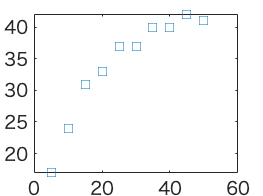

x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];
plot(x, y, 's');

**Linear fit**

poly_order_1 = polyfit(x, y, 1) % n = degree = 1

poly_order_1 =     0.4945   20.6000



xx = 5:2:50; % 5 to 50, steps of 2
yy = polyval(poly_order_1, xx)

yy =    23.0727   24.0618   25.0509   26.0400   27.0291   28.0182   29.0073   29.9964   30.9855   31.9745   32.9636   33.9527   34.9418   35.9309   36.9200   37.9091   38.8982   39.8873   40.8764   41.8655   42.8545   43.8436   44.8327


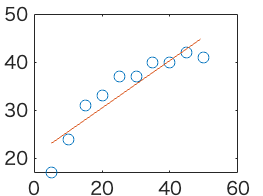

plot(x, y, 'o', xx, yy, '-')


Sr = sum((y - polyval(poly_order_1, x)) .^ 2)

Sr = 97.1636

St = sum((y - mean(y)) .^ 2)

St = 601.6000


linear_r2 = 1 - (Sr/St)

linear_r2 = 0.8385

**Quadratic fit**

poly_order_2 = polyfit(x, y, 2) % n = degree = 2

poly_order_2 =    -0.0161    1.3779   11.7667



xx = 5:2:50; % 5 to 50, steps of 2
yy = polyval(poly_order_2, xx)

yy =    18.2545   20.6248   22.8667   24.9800   26.9648   28.8212   30.5491   32.1485   33.6194   34.9618   36.1758   37.2612   38.2182   39.0467   39.7467   40.3182   40.7612   41.0758   41.2618   41.3194   41.2485   41.0491   40.7212


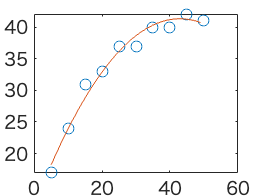

plot(x, y, 'o', xx, yy, '-')


Sr = sum((y - polyval(poly_order_2, x)) .^ 2)

Sr = 12.0424

St = sum((y - mean(y)) .^ 2)

St = 601.6000


quadratic_r2 = 1 - (Sr/St)

quadratic_r2 = 0.9800

**Cubic fit**

poly_order_3 = polyfit(x, y, 3) % n = degree = 3

poly_order_3 =     0.0003   -0.0448    2.0401    8.0333



xx = 5:2:50; % 5 to 50, steps of 2
yy = polyval(poly_order_3, xx)

yy =    17.1580   20.2395   23.0212   25.5199   27.7522   29.7350   31.4848   33.0184   34.3525   35.5038   36.4890   37.3249   38.0281   38.6154   39.1034   39.5089   39.8485   40.1390   40.3971   40.6396   40.8830   41.1441   41.4397


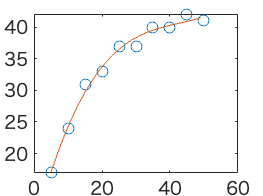

plot(x, y, 'o', xx, yy, '-')


Sr = sum((y - polyval(poly_order_3, x)) .^ 2)

Sr = 6.1944

St = sum((y - mean(y)) .^ 2)

St = 601.6000


cubic_r2 = 1 - (Sr/St)

cubic_r2 = 0.9897

**A power equation fit**

new_power_x = log10(x)

new_power_x =     0.6990    1.0000    1.1761    1.3010    1.3979    1.4771    1.5441    1.6021    1.6532    1.6990


new_power_y = log10(y)

new_power_y =     1.2304    1.3802    1.4914    1.5185    1.5682    1.5682    1.6021    1.6021    1.6232    1.6128



[a, ~] = linregr(new_power_x, new_power_y)

linregr は現在のフォルダーまたは MATLAB パス上に見つかりませんが、次の場所にあります。
 /Users/warissripatoomrak/Documents/GitHub/MATLAB/numerical-methods-finals/lec02/mini-quiz
    /Users/warissripatoomrak/Documents/GitHub/MATLAB/numerical-methods-finals/lec02/practice-questions
    /Users/warissripatoomrak/Documents/GitHub/MATLAB/numerical-methods-finals/lec01
    /Users/warissripatoomrak/Documents/GitHub/MATLAB/numerical-methods-finals/lec03/mini quiz

MATLAB の現在のフォルダーを変更 または そのフォルダーを MATLAB パスに追加。


power_slope = a(1)
power_intercept = a(2)
alpha = power(10, power_intercept)
beta = power_slope

xp = linspace(min(x), max(x), 100)
yp = alpha * power(xp, beta)
plot(x, y, '*', xp, yp, '-')

y_pred_power = alpha * power(x, beta)

Sr = sum((y - y_pred_power) .^ 2)
St = sum((y - mean(y)) .^ 2)
power_r2 = 1 - (Sr/St)

**A saturation-growth-rate equation fit**

new_sat_x = 1 ./ x
new_sat_y = 1 ./ y

[a, r2] = linregr(new_sat_x, new_sat_y)

sat_slope = a(1)
sat_intercept = a(2)
alpha = 1 / sat_intercept
beta = sat_slope * alpha

xp = linspace(min(x), max(x), 100)
yp = alpha .* (xp ./ (beta + xp))
plot(x, y, '*', xp, yp, '-')

y_pred_sat = alpha .* (x ./ (beta + x))

Sr = sum((y - y_pred_sat) .^ 2)
St = sum((y - mean(y)) .^ 2)
sat_r2 = 1 - (Sr/St)